## Running the Equiluminance Data Files to Extract Eye Position

Our dataset is generated using the code in [https://github.com/iandol/equiluminance](https://github.com/iandol/equiluminance) -- this repo contains both the experiment code and analysis code from the paper: [https://www.nature.com/articles/s41598-024-51982-z](https://www.nature.com/articles/s41598-024-51982-z)

You need to add the equiluminance github to the MATLAB path and it depends on Opticka [https://github.com/iandol/opticka](https://github.com/iandol/opticka) as opticka contains the edfmex loading functions, base classes and other analysis code.

The experiment generates an `EDF` and `MAT` file with the same filename. The MAT file specifies all the experiment settings. To load data and run the pupilPower analysis use the `pupilPower` class; the run method will ask for an EDF file, there should be a matching MAT file in the same folder which specified the trial data:

p = pupilPower;

---> pupilPower#13097F5FD: You should REPARSE the data to fully enable this change
calibrateLuminance<1AACF535A> Deleting: 1AACF535A | DELETE Method


---> stimulusSequence loadobj: Rebuilding  structure...

--->>> LOADING raw EDF data: 
Loading:100%
:#: Loading Raw EDF Data took 2.92 secs
Parsing Eyelink Events: [====================] Done. [1 seconds]      
Simple Parsing of EDF Trials took 1.04 secs
---> pupilPower FFT calculation took 0.217 secs


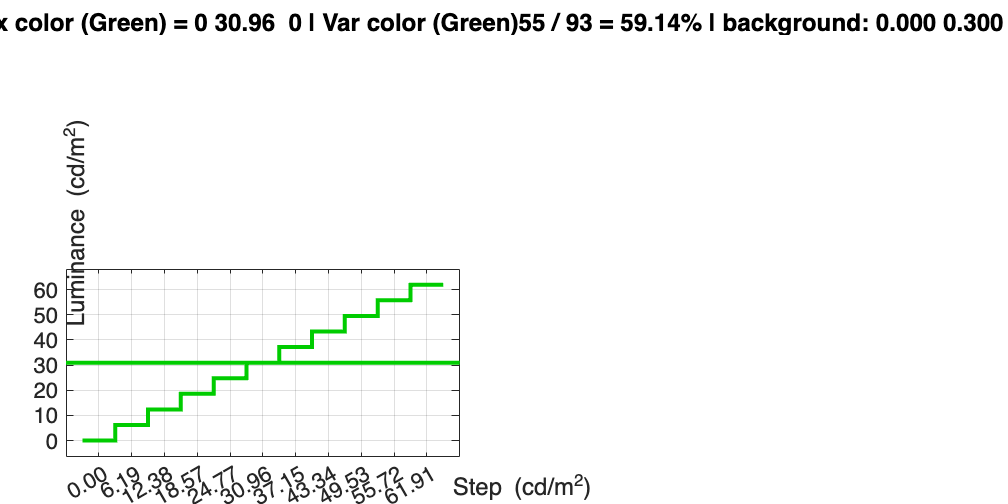

           sse: 0.0424
       rsquare: 0.9132
           dfe: 3.7221
    adjrsquare: 0.7668
          rmse: 0.1068



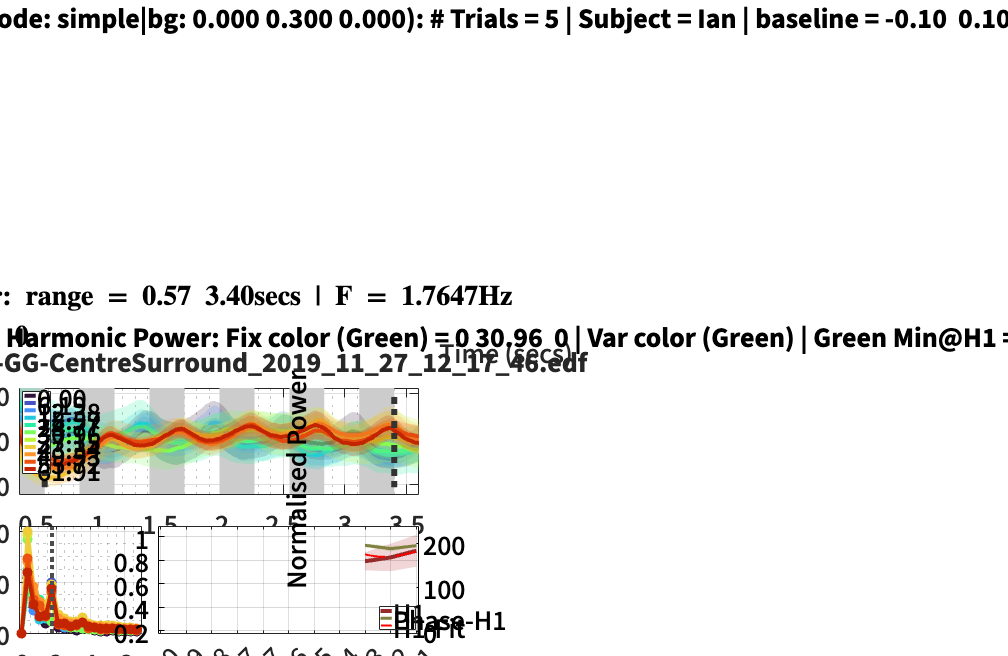

p.run; 

This code loads the EDF and parses it into trials.

## Finding the raw data

You should see the result of the pupilPower analysis as a plot segmented into averaged trials for each luminance used. Each luminance variable has a different oscillation amplitude, choose one with the biggest amplitude. Now pupilPower extracts only the pupil signal locked to stimulus onset, yet the parsed EDF is  available in the `pupilData` property:

data = p.pupilData; % raw and parsed eyelink data

---> : You should REPARSE the data to fully enable this change


disp(data)

  eyelinkAnalysis with properties:

                     file: 'IsoLum_Ian-GG-CentreSurround_2019_11_27_12_17_46.edf'
                      dir: '/Users/ian/'
    trialStartMessageName: 'TRIALID'
      variableMessageName: 'TRIALID'
           rtStartMessage: 'END_FIX'
             rtEndMessage: 'END_RT'
          trialEndMessage: 'TRIAL_RESULT'
        rtOverrideMessage: 'SYNCTIME'
       minSaccadeDistance: 1
                     VFAC: 5
                   MINDUR: 2
                       tS: [0×0 struct]
         excludeIncorrect: 0
                      ROI: []
                      TOI: []
                  verbose: 0
              pixelsPerCm: 27
                 distance: 68
              useDiameter: {[0]  [9250]  [8]}
                 isParsed: 1
               sampleRate: 1000
                      raw: [0×0 struct]
                   trials: [1×93 struct]
                     vars: [1×11 struct]
     

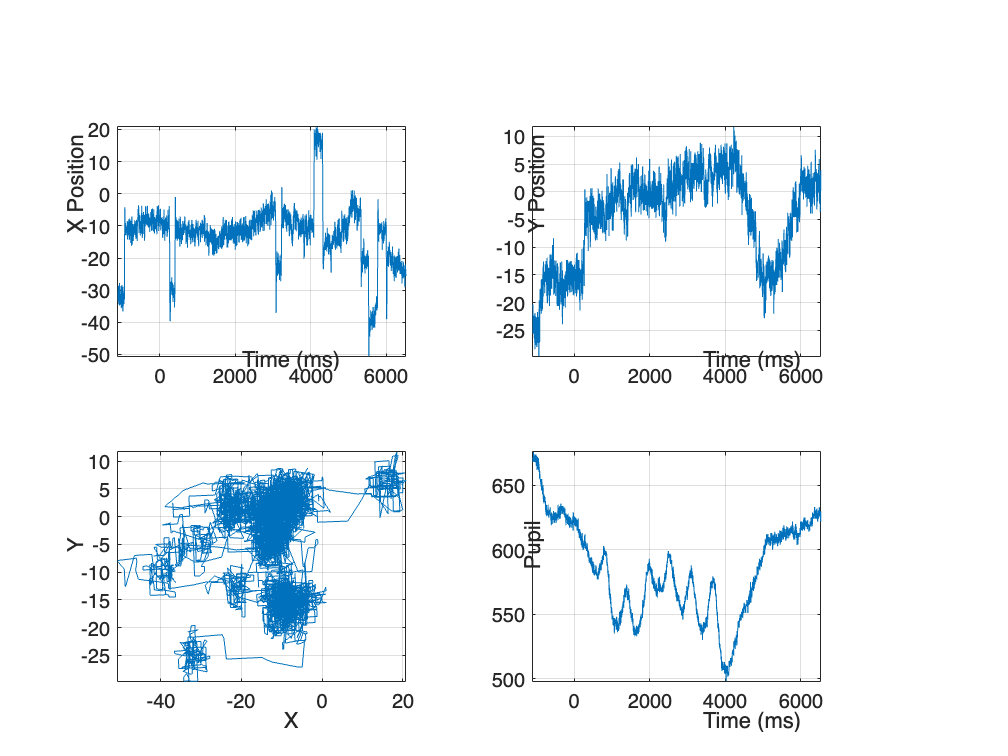

var1 = data.vars(1); % first varible (in this case luminance)

figure;
t=tiledlayout(2,2);
nexttile(t);
plot(var1.trial(1).times,var1.trial(1).gx);
xlabel('Time (ms)'); ylabel('X Position');grid on;axis tight;
nexttile(t);
plot(var1.trial(1).times,var1.trial(1).gy);
xlabel('Time (ms)'); ylabel('Y Position');grid on; axis tight;
nexttile
plot(var1.trial(1).gx,var1.trial(1).gy);
xlabel('X'); ylabel('Y');grid on; axis tight;
nexttile
plot(var1.trial(1).times,var1.trial(1).pa);
xlabel('Time (ms)'); ylabel('Pupil');grid on; axis tight;

This plots the X and Y data linked to stimulus onset for the first trial of the first variable. The raw trials are in `data.trials` which include all variables and both correct and incorrect trials. `data.vars` should include only correct trials for that variable. 